
fprintf("hello")

hello

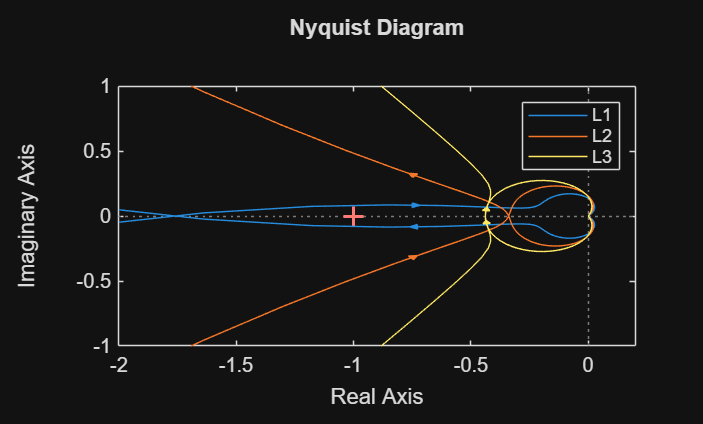

%Part a)
s = tf('s');
C1 = (770*s+350)/(s*4.3+1);
C2 = (770*s+210)/(2.5*s+1);
C3 = (770*s+140)/(1.7*s+1);

num_GI = [5.1e-3 100 250];
den_GI = [5e5 2.5e5 6.4e5 4.9e4 0];

% Transfer function G_I(s)
G_I = tf(num_GI, den_GI);

L1 = G_I*C1;
L2 = G_I*C2;
L3 = G_I*C3;


nyquist(L1)
hold on
nyquist(L2)
hold on
nyquist(L3)
xlim([-2,0.2])
ylim([-1,1])
hold off
legend


%Part b) 
%Use the Nyquist contours from question a) to determine, for each controller, whether the
%closed-loop interconnection in Figure 2 is stable. Please explain briefly how you came to
%this conclusion by making reference to the Nyquist stability criterion. 

% It is clear that since the blue line contours the unstable point L1 is
% unstable

%L2 is stable as it does not surround the unstable point
%L3 is stable as well as it doesn't contour the unstable point

%Part c)
%For each open-loop system Li(s)—with i = 1,2,3—determine the crossover frequency ωc in
%rad/s
% the phase margin PM in degrees, the gain margin GM in dB and the modulus margin MM
%in dB. You may round off your answer to one decimal place.
% Put the systems into a cell array for easy looping


% Put the systems into a cell array for easy looping
% Put the systems into a cell array
systems = {L1, L2, L3};
labels = {'L1', 'L2', 'L3'};

fprintf('--- Stability Margins Analysis ---\n');

--- Stability Margins Analysis ---



for i = 1:3
    L = systems{i};
    stats = allmargin(L);
    
    % 1. Crossover Frequency (wc)
    wc = stats.PMFrequency(1);
    
    % 2. Phase Margin (PM)
    PM = stats.PhaseMargin(1);
    
    % 3. Gain Margin (GM) in dB
    GM_dB = 20*log10(stats.GainMargin(1));
    
    % 4. Modulus Margin (MM) - THE ROBUST WAY
    % S is the Sensitivity Function: S = 1 / (1 + L)
    S = feedback(1, L); 
    
    % The peak magnitude of the sensitivity function is M_s
    % The Modulus Margin is 1/M_s
    [Ms, ~] = norm(S, inf); 
    MM_linear = 1/Ms;
    MM_dB = 20*log10(MM_linear);
    
    % Display Results
    fprintf('%s Results:\n', labels{i});
    fprintf('   Crossover Freq (wc): %.1f rad/s\n', wc);
    fprintf('   Phase Margin (PM):   %.1f degrees\n', PM);
    fprintf('   Gain Margin (GM):    %.1f dB\n', GM_dB);
    fprintf('   Modulus Margin (MM): %.1f dB\n', MM_dB);
    fprintf('----------------------------------\n');
end

L1 Results:


   Crossover Freq (wc): 0.3 rad/s


   Phase Margin (PM):   -4.8 degrees


   Gain Margin (GM):    -5.0 dB


   Modulus Margin (MM): -21.6 dB


----------------------------------


L2 Results:


   Crossover Freq (wc): 0.3 rad/s


   Phase Margin (PM):   24.9 degrees


   Gain Margin (GM):    9.4 dB


   Modulus Margin (MM): -7.9 dB


----------------------------------


L3 Results:


   Crossover Freq (wc): 0.3 rad/s


   Phase Margin (PM):   45.9 degrees


   Gain Margin (GM):    7.2 dB


   Modulus Margin (MM): -5.0 dB


----------------------------------


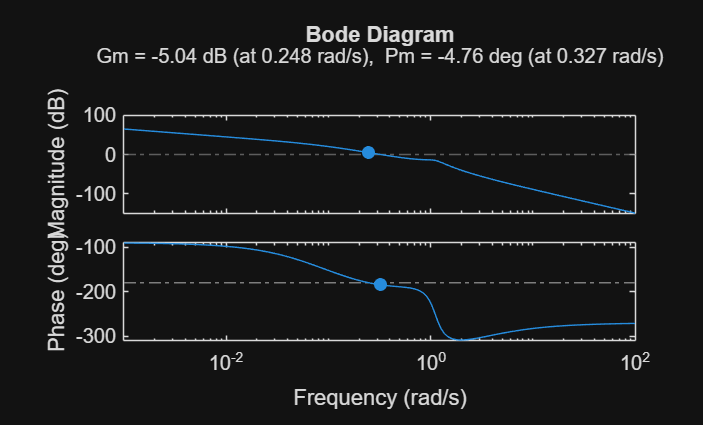


% 2. Visual: Plot Bode with Margins annotated
figure;
margin(L1);

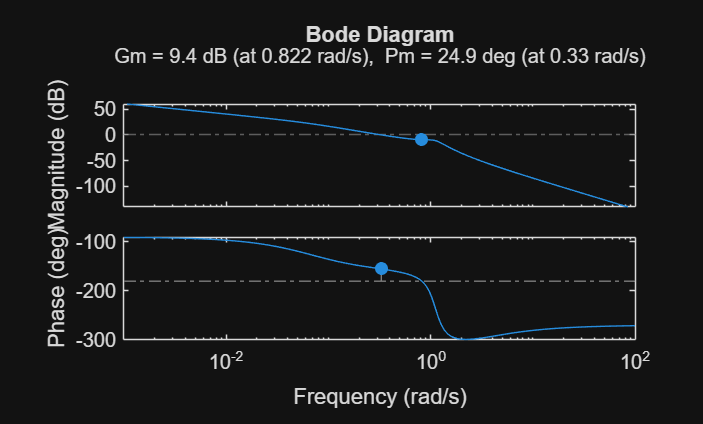

margin(L2);

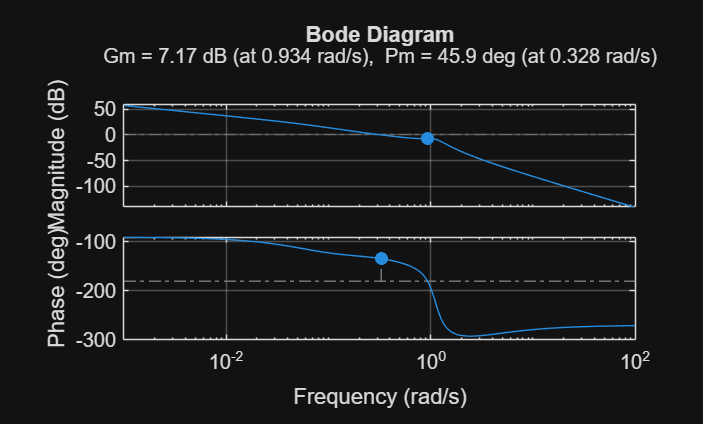

margin(L3);
grid on;


[Gm1, Pm1, Wcg1, Wcp1] = margin(L1);

[Gm2, Pm2, Wcg2, Wcp2] = margin(L2);
[Gm3, Pm3, Wcg3, Wcp3] = margin(L3);


% Display results
fprintf('Gain Margin L1: %.2f dB\n', 20*log10(Gm1));

Gain Margin L1: -5.04 dB


fprintf('Phase Margin L1: %.2f degrees\n', Pm1);

Phase Margin L1: -4.76 degrees


fprintf('Open-Loop Crossover L1: %.2f rad/s\n', Wcp1);

Open-Loop Crossover L1: 0.33 rad/s



fprintf('Gain Margin L2: %.2f dB\n', 20*log10(Gm2));

Gain Margin L2: 9.40 dB


fprintf('Phase Margin L2: %.2f degrees\n', Pm2);

Phase Margin L2: 24.86 degrees


fprintf('Open-Loop Crossover L2: %.2f rad/s\n', Wcp2);

Open-Loop Crossover L2: 0.33 rad/s



fprintf('Gain Margin L3: %.2f dB\n', 20*log10(Gm3));

Gain Margin L3: 7.17 dB


fprintf('Phase Margin L3: %.2f degrees\n', Pm3);

Phase Margin L3: 45.87 degrees


fprintf('Open-Loop Crossover L3: %.2f rad/s\n', Wcp3);

Open-Loop Crossover L3: 0.33 rad/s



%part d)

T1 = feedback(L1,1)


T1 =
 
                   3.927 s^3 + 7.7e04 s^2 + 227500 s + 87500
  ---------------------------------------------------------------------------
  2.15e06 s^5 + 1.575e06 s^4 + 3.002e06 s^3 + 9.277e05 s^2 + 276500 s + 87500
 
Continuous-time transfer function.


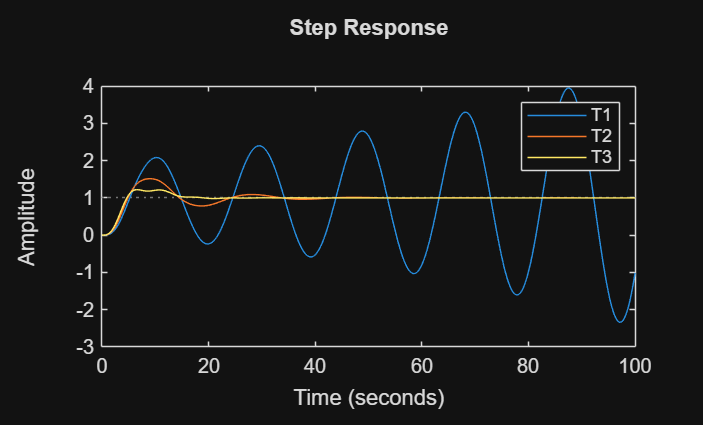

T2 = feedback(L2, 1);
T3 = feedback(L3, 1);


step(T1, 100)
hold on 
step(T2, 100)
hold on
step(T3, 100)
legend
hold off

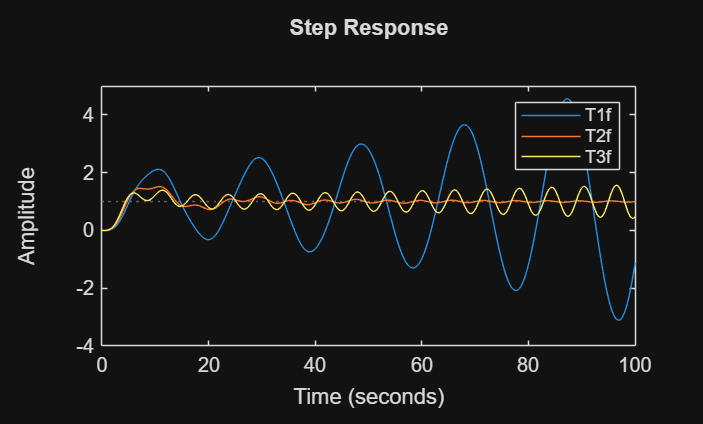


%part e)

% How well do T1, T2, T3 do they track the step reference signal?
% T1 is unstable and so it performs poorly in the step response
% T2 is stable so performance is decent
% T3 is stable so performance is good

%comparison on overshoot, SSE and settling time for criteria each
%controller

% overshoot C3 is the clear winner it is quite a bit more damped than the
% other controller and has the least overshoot

%In the end C3 again has the lowest SSE at exactly 1 and it reaches this
%point before any other controller while C1 never quite reaches the target

%settling time is again lowest for T3 therefore overall T3's performance
%tops the other 2 controllers and closed looped systems


%part f)

num_GIf = [5.1e-3 10 250];
den_GIf = [5e5 7e4 6.2e5 4.9e4 0];

% Transfer function G_I(s)
G_If = tf(num_GIf, den_GIf);
L1f = G_If*C1;
L2f = G_If*C2;
L3f = G_If*C3;

T1f = feedback(L1f, 1);
T2f = feedback(L2f, 1);
T3f = feedback(L3f, 1);

step(T1f, 100)
hold on 
step(T2f, 100)
hold on
step(T3f, 100)
legend
hold off


%part g)
%whats the difference in step responses?
% it seems that the change in dampening in the long term affected the
% controllers by making their steady state error greater, and so affecting
% settling time.


%how is it affected by change in parameters
%everything is a lot more unstable


%how robust is each of these controllers?
%It seems like T2f is more robust than T3f however, I don't understand why
%as the MM for C3 in the nyquist seemed greater than C2??

%part h)
%find sensitivity function of T1, T2, T3

S1 = feedback (1, L1);
S2 = feedback(1, L2);
S3 = feedback(1, L3);

% Calculate the Maximum Sensitivity (Ms)
Ms1 = getPeakGain(S1);
Ms2 = getPeakGain(S2);
Ms3 = getPeakGain(S3);

% Display the results
fprintf('Ms for System 1: %.4f\n', Ms1);

Ms for System 1: 12.0721


fprintf('Ms for System 2: %.4f\n', Ms2);

Ms for System 2: 2.4825


fprintf('Ms for System 3: %.4f\n', Ms3);

Ms for System 3: 1.7800



%analysing all systems the 3rd one is most robust even though the
%performance is not as optimal
%higher robustness /=/ higher performance

%part g) complementary sensitvity
% --- A. Peak Resonance (Mt) ---
% Tells us about Overshoot.
% Mt > 1.3 (approx 2.3 dB) usually means noticeable ringing.
Mt1 = getPeakGain(T1);
Mt2 = getPeakGain(T2);
Mt3 = getPeakGain(T3);

% --- C. Noise Rejection Check (High Freq Magnitude) ---
% We check the magnitude at a high frequency (e.g., 1000 rad/s)
% Ideally, this number should be TINY (e.g., < 0.01 or -40dB).
w_noise = 10; 
NoiseReject1 = abs(freqresp(T1, w_noise));
NoiseReject2 = abs(freqresp(T2, w_noise));
NoiseReject3 = abs(freqresp(T3, w_noise));

%% 4. Display Stats Table
fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('%-10s | %-12s | %-12s | %-15s\n', 'System', 'Peak (Mt)', 'Bandwidth', 'Noise Gain @1k');

System     | Peak (Mt)    | Bandwidth    | Noise Gain @1k 


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('T1         | %.4f       | %.4f rad/s | %.6f\n', Mt1, Wcp1, NoiseReject1);

T1         | 12.1870       | 0.3267 rad/s | 0.000037


fprintf('T2         | %.4f       | %.4f rad/s | %.6f\n', Mt2, Wcp2, NoiseReject2);

T2         | 2.3283       | 0.3299 rad/s | 0.000064


fprintf('T3         | %.4f       | %.4f rad/s | %.6f\n', Mt3, Wcp3, NoiseReject3);

T3         | 1.3247       | 0.3285 rad/s | 0.000094


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


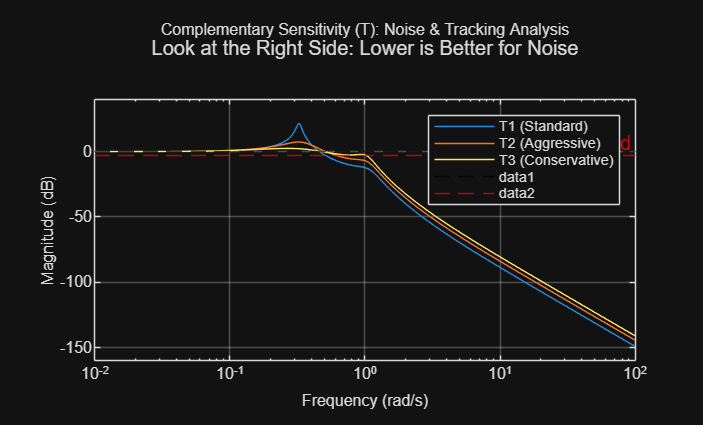


%% 5. Plotting for Visual Analysis
figure;
opts = bodeoptions;
opts.FreqUnits = 'rad/s';
opts.MagUnits = 'dB';
opts.Grid = 'on';

% Plot all three
bodemag(T1, T2, T3, opts);
legend('T1 (Standard)', 'T2 (Aggressive)', 'T3 (Conservative)');
title('Complementary Sensitivity (T): Noise & Tracking Analysis');
subtitle('Look at the Right Side: Lower is Better for Noise');

% Add a line at 0dB (Ideal Tracking) and -3dB (Bandwidth limit)
yline(0, 'k--'); 
yline(-3, 'r--', 'Bandwidth Threshold');

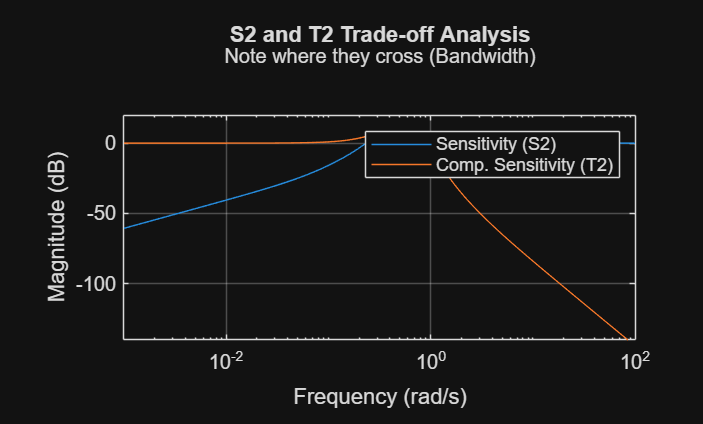


% what can we say about high-frequency noise rejection in the end it seems
% like T1 (C1 controller) has the best tolerance for dealing with
% rejection of noise so in terms of that this is the best controller
% however since its sensitivity and robustness are terrible and unstable so
% overall wouldn't be the right pick. 

% part j) 
% 2. Plot them TOGETHER to see the trade-off
figure;
bodemag(S2, T2); 
grid on;
legend('Sensitivity (S2)', 'Comp. Sensitivity (T2)');
title('S2 and T2 Trade-off Analysis');
subtitle('Note where they cross (Bandwidth)');


% 3. Verify the identity S + T = 1
% Method A: Visual/Numerical Check
Identity_Check = S2 + T2; 
minreal(Identity_Check) % This should output "1"


ans =
 
  1
 
Static gain.


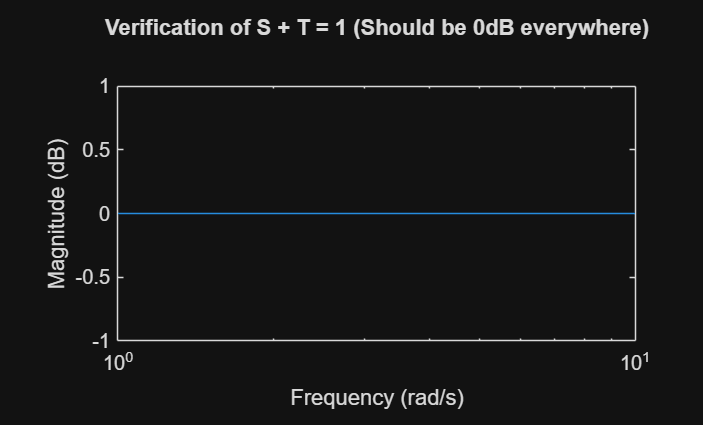


% Method B: Plot the sum (Should be a flat line at 0 dB)
figure;
bodemag(S2 + T2);
title('Verification of S + T = 1 (Should be 0dB everywhere)');


%What can we say about the trade-off between tracking performance and noise rejection?
% we can clearly tell that S and T have a contradictory property where if 1
% increases the other decreases
%The identity is always respect no matter what
%High gain feedback
%bode sensitivity integral will always stay like this

%{
The trade-off between tracking performance and noise rejection is governed
by the algebraic identity $S(s) + T(s) = 1$. This identity implies a
fundamental conflict: we cannot simultaneously minimize the Sensitivity
($S$) for good tracking and the Complementary Sensitivity ($T$) for good
noise rejection at the same frequency.

To achieve good tracking performance at low frequencies, we typically use
high-gain feedback (large loop gain $L$). This forces $|S| \approx 0$, which
implies that $|T| \approx 1$. Consequently, while the system tracks the
reference well, it passes sensor noise through to the output with almost
no attenuation ($T \approx 1$).

Conversely, at high frequencies where we want to reject noise (require
$|T| \approx 0$), we are forced to accept poor tracking ($|S| \approx 1$).

Finally, the Bode Sensitivity Integral (or 'waterbed effect') tells us
that we pay a price for this performance. By using high gain to push $|S|$
down at low frequencies, the area under the sensitivity curve is
conserved, causing $|S|$ to 'pop up' and potentially exceed 1 at higher
frequencies. This creates a peak in sensitivity that reduces the
system's robustness.
%}